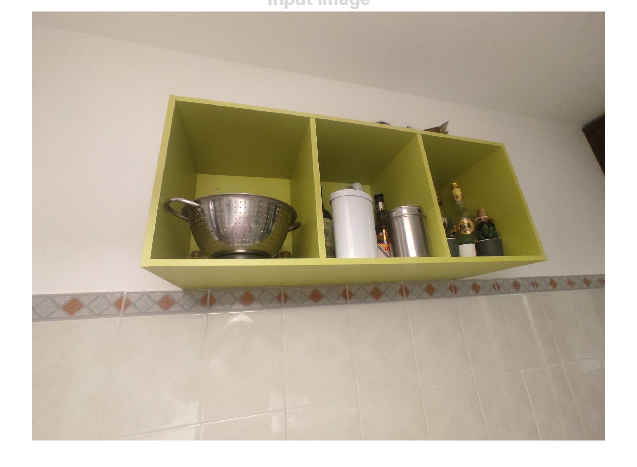

img = imread('Look-outCat.jpg');
imshow(img);
title('Input Image');

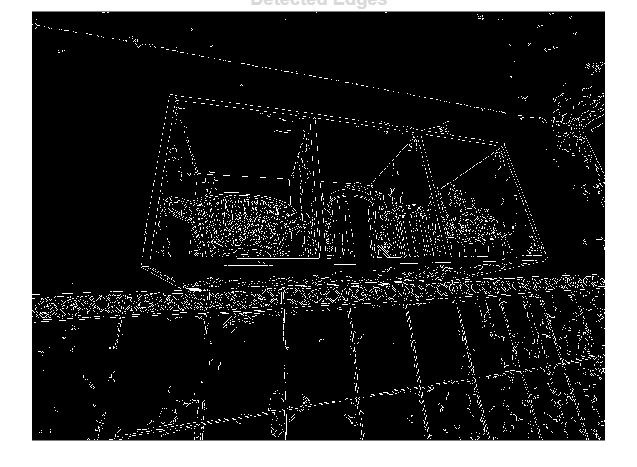

% Convert the image to grayscale
grayImg = rgb2gray(img);

% Edge detection
edges = edge(grayImg, 'Canny');

% Display edges
figure;
imshow(edges);
title('Detected Edges');

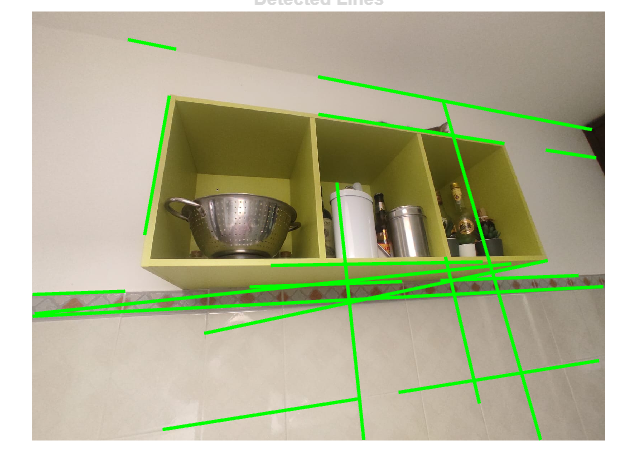


% Hough Transform for line detection
[H, T, R] = hough(edges);
peaks = houghpeaks(H, 50, 'threshold', ceil(0.5 * max(H(:))));
lines = houghlines(edges, T, R, peaks, 'FillGap', 100, 'MinLength', 120);

% Display detected lines
figure;
imshow(img);
hold on;
for k = 1:length(lines)
    xy = [lines(k).point1; lines(k).point2];
    plot(xy(:,1), xy(:,2), 'LineWidth', 2, 'Color', 'green');
end
hold off;
title('Detected Lines');

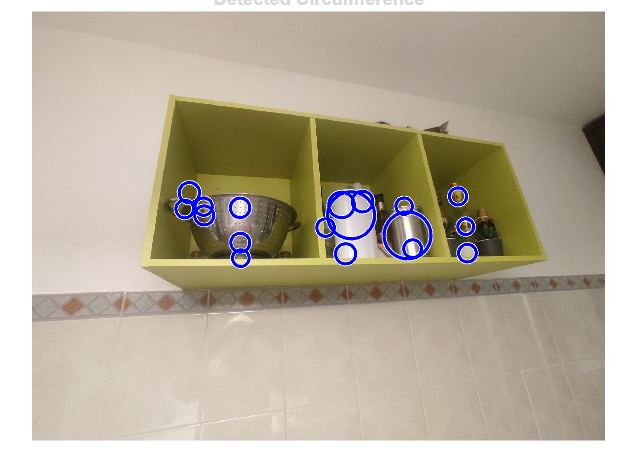

% Detect circles using imfindcircles
[centers, radii] = imfindcircles(grayImg, [20 100], 'Sensitivity', 0.95);

% Display the circles
figure;
imshow(img);
hold on;
viscircles(centers, radii, 'EdgeColor', 'b');
hold off;
title('Detected Circumference');

% Use edge-based detection for curves
curves = bwboundaries(edges, 'noholes');

% Visualize one of the detected curves (manual selection may be required)
figure;
imshow(img);
hold on;
for k = 1:length(curves)
    plot(curves{k}(:,2), curves{k}(:,1), 'r', 'LineWidth', 2);
end
hold off;
title('Detected Planar Curves');

save('extracted_features.mat', 'lines', 'centers', 'radii', 'curves');
